% Tr1b=TrPC;
ops.nC = 40;%, number of clusters to use 
ops.iPC = 1:100;%, number of PCs to use 
ops.isort = [];%, initial sorting, otherwise will be the top PC sort
ops.useGPU = 0;%, whether to use the GPU
ops.upsamp = 100;%, upsampling factor for the embedding position
ops.sigUp = 1;%, % standard deviation for upsampling
[isort1, isort2, Sm] = mapTmap(Tr1b,ops);

Elapsed time is 4.708199 seconds.
Elapsed time is 5.518495 seconds.


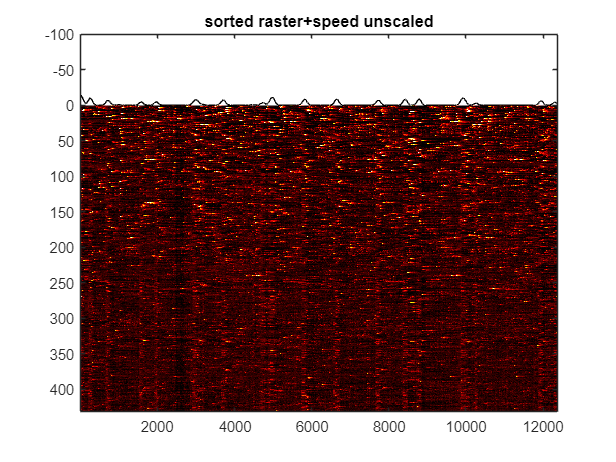

% [isort1, isort2, Sm] = mapTmap(DF,ops);

figure
Ftemp=smoothdata(Tr1b,2,"gaussian",20);

minDF=prctile(Ftemp(:),5);
maxDF=prctile(Ftemp(:),99.9);
% imagesc(Ftemp(isort1,:))
imagesc(Ftemp)
clim ([minDF maxDF])
colormap ("hot")
hold on

plot (-speed*3,'Color','k')

% plot (-binary_signal*20)
% plot (-cumulativeDistance/10)
% plot (-position_round,'Color','r')
ylim([-100 NCell]) 
% drawnow
hold off
title('sorted raster+speed unscaled')

% pause(1)
% 
% if savefig==1
%     exportgraphics(gcf,[namefull 'rastermap.png'],'Resolution',300)
%     close gcf
%     raster = Picture([namefull 'rastermap.png']);
% end

return

%% % all colors
nbR=sum(colorcell==1);
nbG=sum(colorcell==2);
nbB=sum(colorcell==3);
nbRG=sum(colorcell==4);
nbRB=sum(colorcell==5);
nbGB=sum(colorcell==6);
nball=sum(colorcell==7);
nbnone=sum(colorcell==8);

total=nbR+nbG+nbB+nbRG+nbRB+nbGB+nball+nbnone;
    
color_all=[nbR nbG nbB nbRG nbRB nbGB nball nbnone];
labels = {'Red','Green','Blue' 'Red/Green' 'Red/Blue' 'Green/Blue' 'All' 'none'};
explode = [1 1 1 1 1 1 1 1];
figure('visible','off');
pie(color_all, explode)
colormap([1 0 0;      %// red
          0 1 0;      %// green
          0 0 1;      %// blue
          1 1 0; %YELLOW
          1 0 1; %magenta
          0 1 1; %cyan
          1 1 1;
          0 0 0])  %white
          
title 'color all GCaMP cells'
namegraph=[namefull 'color_all_GCaMP_cells.png'];

if savefig==1
    exportgraphics(gcf, namegraph,'Resolution',300)
    close gcf
end

%%mask all cells


## show color all cells

% fig = figure('visible','off');
figure('visible','off');
colormap ("gray")
imagesc(calcium)
title ('all cells','Position', [0, 1.3, 0],'FontSize',16);
hold on

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell

    if colorcell(n)==1
        col='red';
    elseif colorcell(n)==2 
        col='green';
    elseif colorcell(n)==3 
        col='blue';
    elseif colorcell(n)==4 
        col='yellow';
    elseif colorcell(n)==5 
        col='magenta';
    elseif colorcell(n)==6 
        col='cyan';
    elseif colorcell(n)==7 
        col='white';
    elseif colorcell(n)==8 
        col='black';
    end

    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    patch(x, y,col,'FaceAlpha', 1,'EdgeColor','k','LineWidth',1)

    % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    %plot(x, y, '.', 'MarkerSize', 4,"Color",col);
    axis off
    axis image
        

end
hold off
namegraph=strcat(namefull,['allcells' , '.png']);
if savefig==1
    exportgraphics(gcf, namegraph,'Resolution',300)
    close gcf
end